# Use of k-means clustering to identify tumor in skin cut

François Paupier, *2018 Centrale Nantes engineering School.*

**Goal: **Perform automatic segmentation of the dermis, epidermis and tumor in a skin cut			

**Solution**: Use of kmean clustering with colors and other engineered features.

## **Load the images**

close all;
skin1 = imread('skin.jpg');
skin2 = imread('skin_tumor.jpg');

## Plot raw data

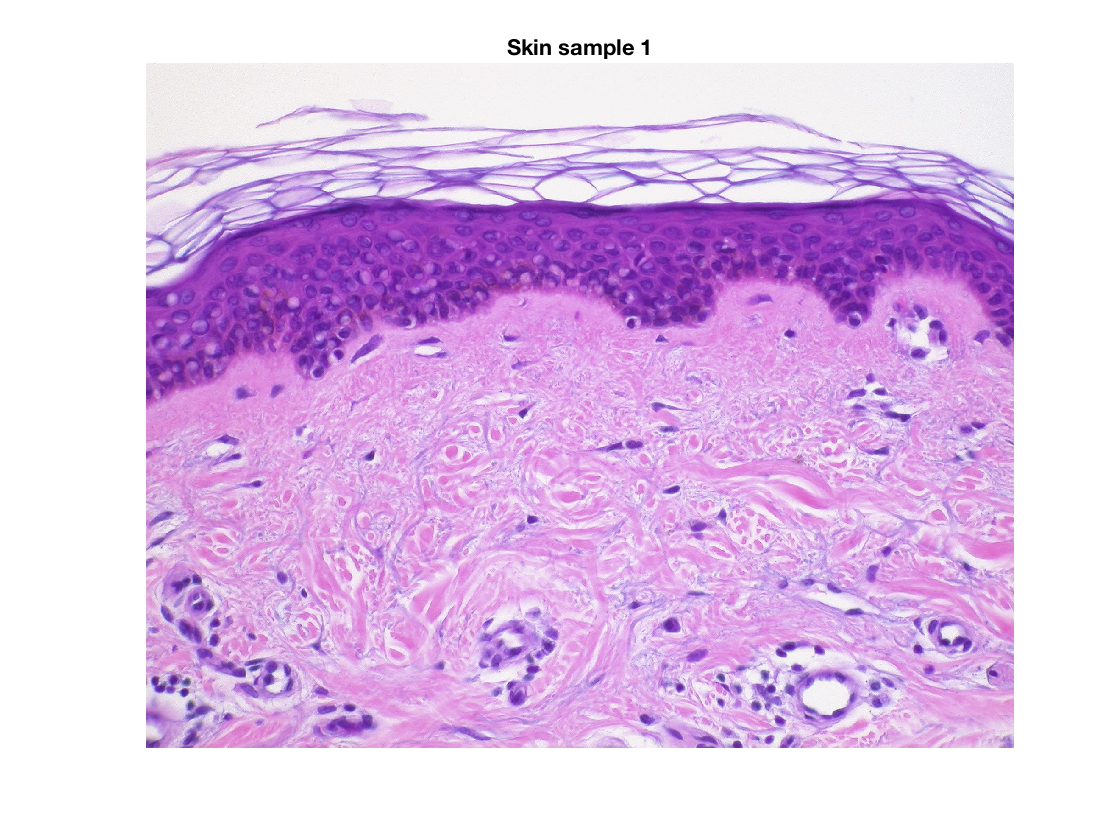

figure(1);
imagesc(skin1);
title('Skin sample 1')
axis off;

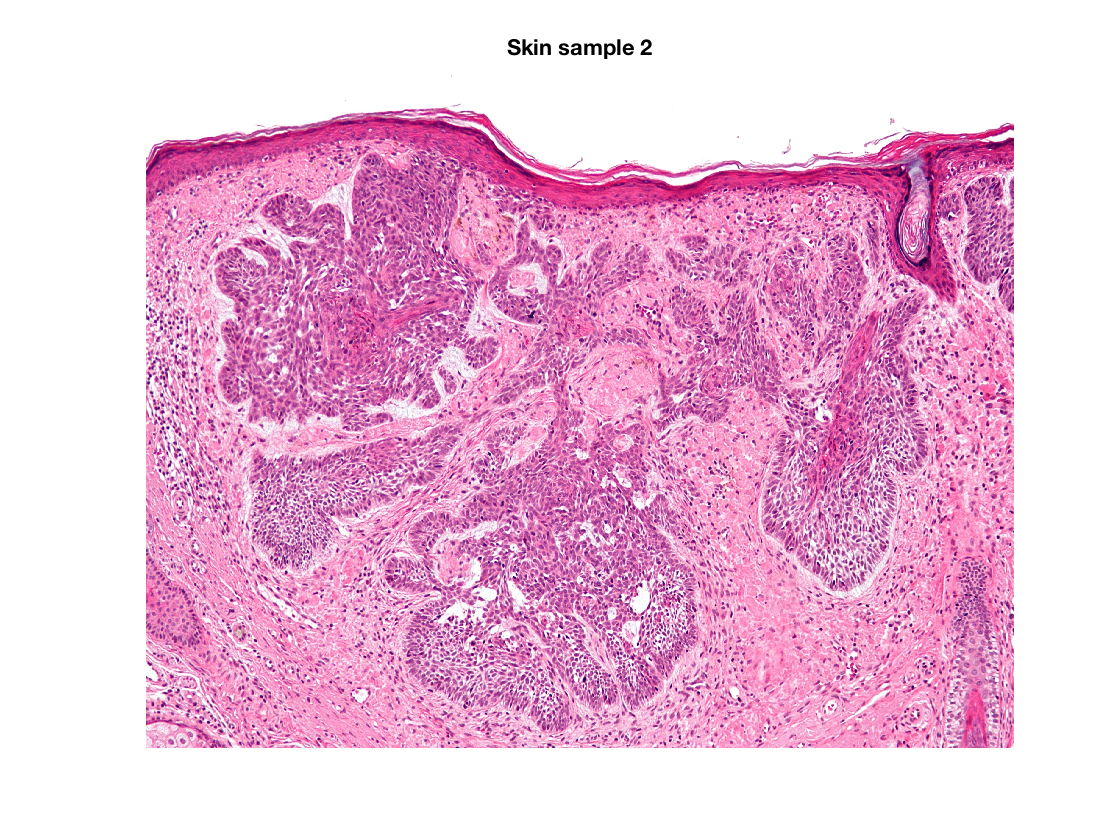

figure(2);
imagesc(skin2);
title('Skin sample 2')
axis off;

*Observations:*

    We note that we can roughly estimate the regions of interests on those samples but the definition of the boundary may differ from person to person. An unbiased model may be of great help in such cases.

**I  use two different sets of features to fed the *****k-means***** and compare their results**

**    - using colors as features**

**    - using convolution of the base image with patches from the region of interests as features**

In a nutshell, using the features from the convolution yield much better results.

In both cases I use 4-means clustering because we work with 4 classes;

- dermis

- epidermis

- tumor

- none of the above

## 1. First method: Using colors as features

## On skin sample 1

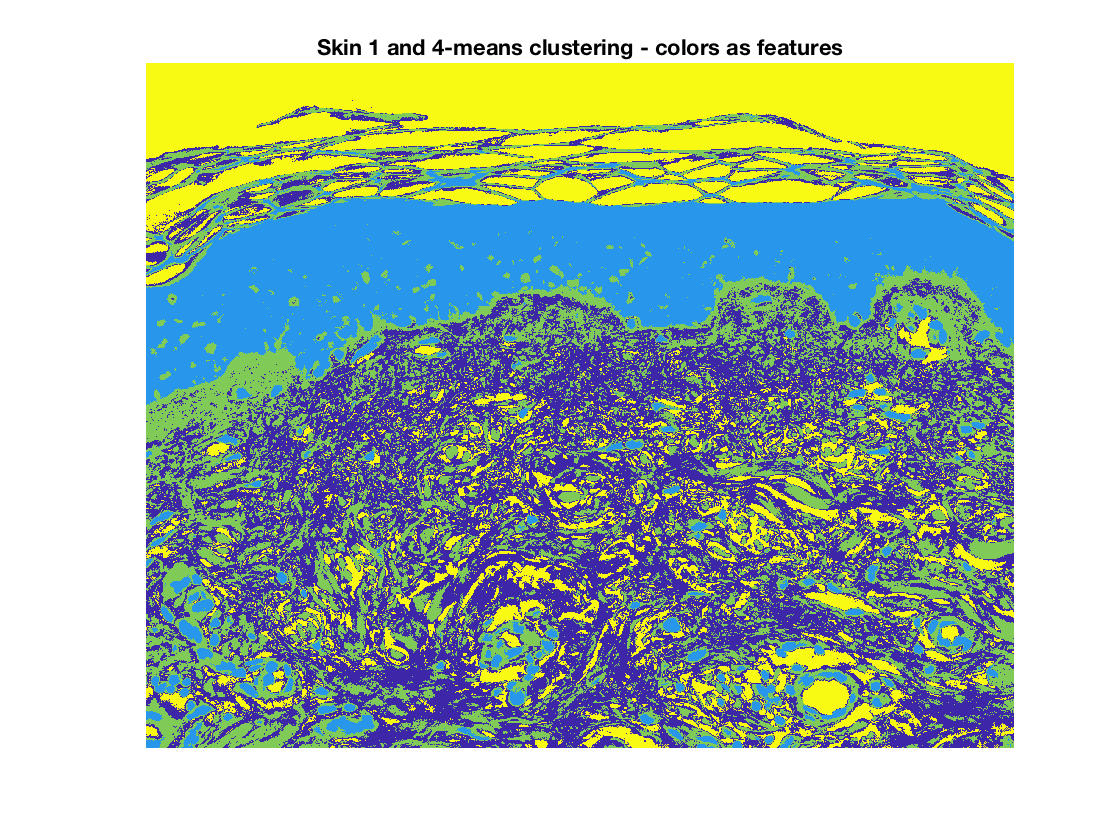

Xskin1x = skin1(:,:,1);
Xskin1y = skin1(:,:,2);
Xskin1z = skin1(:,:,3);
Xskin1 = double([Xskin1x(:),...
                 Xskin1y(:),...
                 Xskin1z(:)]);
             
[m, n] = size(Xskin1x);
idxSkin1 = kmeans(Xskin1, 4);
skin1_reconstructed = reshape(idxSkin1, m, n);

figure(3)
imagesc(skin1_reconstructed);
title('Skin 1 and 4-means clustering - colors as features')
axis off;

## On skin sample 2

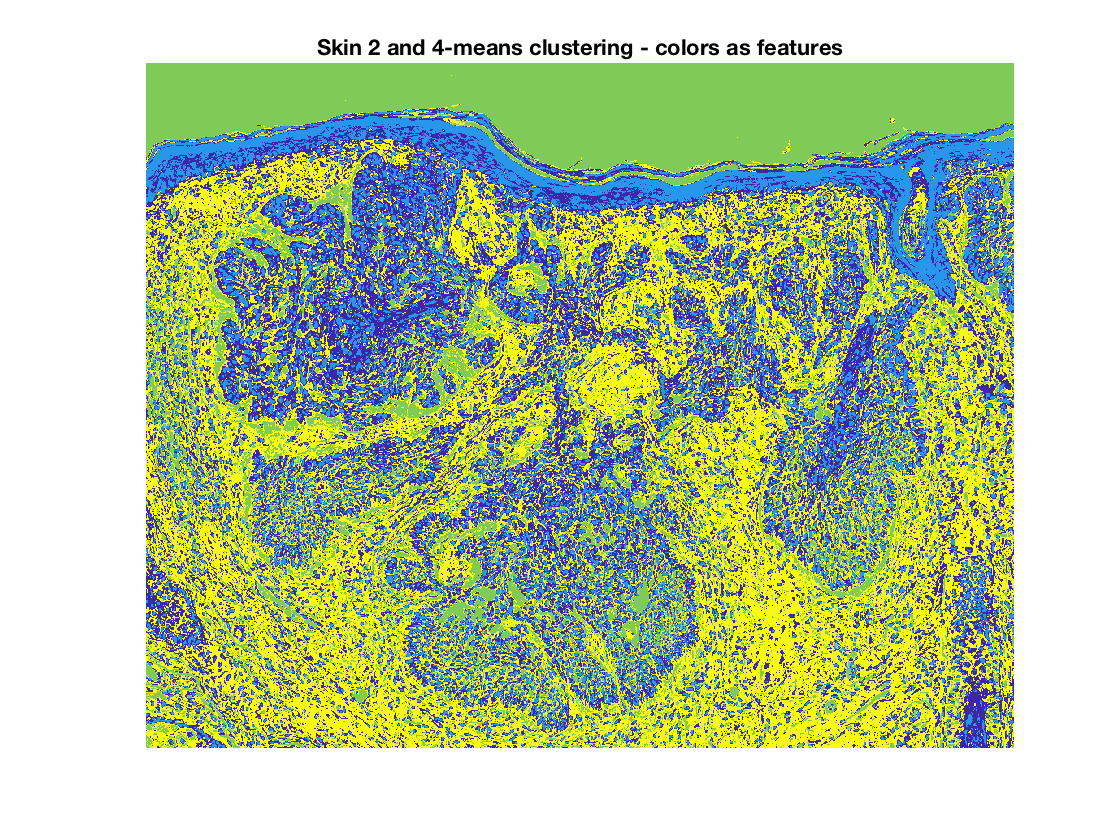

Xskin2x = skin2(:,:,1);
Xskin2y = skin2(:,:,2);
Xskin2z = skin2(:,:,3);
Xskin2 = double([Xskin2x(:),...
                Xskin2y(:),...
                Xskin2z(:)]);
            
[m2, n2] = size(Xskin2x);

idxSkin2 = kmeans(Xskin2, 4);

skin2_reconstructed = reshape(idxSkin2, m2, n2);

figure(4)
imagesc(skin2_reconstructed);
title('Skin 2 and 4-means clustering - colors as features')
axis off;

*Observations:*

    		With a 4-means clustering based only on colors we notice that the classification is not relevant. Indeed, it doesn't provide homogenous zones but a mixed patchwork. 

Concerning the skin sample 2, the original image may be of better use to a doctor to assess the tumor infiltration.

Colors only are not good features for classification of a skin cut using kmeans algorithm.

## 2. Second method: Using patch of regions of interest as features

In this approach we use higher levels features.

We build features by convoluting the skin images with an extract of a region of interest (let's say a typical dermis region). We iterate for each regions of interest.

Those samples of ROI (*Region of interest)* are chosen manually to be "good" representatives of the concerned tissue. 

We define and choose the three following features:

- The convolution of the base image and a patch from the dermis

- The convolution of the base image and a patch from the epidermis

- The convolution of the base image and a patch from the tumor (if tumor in the image)

This is semi-supervised learning since we define the patch of tissue to consider for the convolution.

## Skin sample 1

skin1G = double(rgb2gray(skin1));

kernel_derme1 = skin1G(550:630, 820:880);
kernel_epiderme1 = skin1G(180:220, 260:290);
feature_derme1 = imfilter(skin1G, kernel_derme1);
feature_epiderme1 = imfilter(skin1G, kernel_epiderme1);
[m, n] = size(feature_derme1);
Xskin1 = [feature_derme1(:),...
          feature_epiderme1(:)];
          idxSkinF1 = kmeans(Xskin1, 4);

Draw the feature map associated with the dermis:

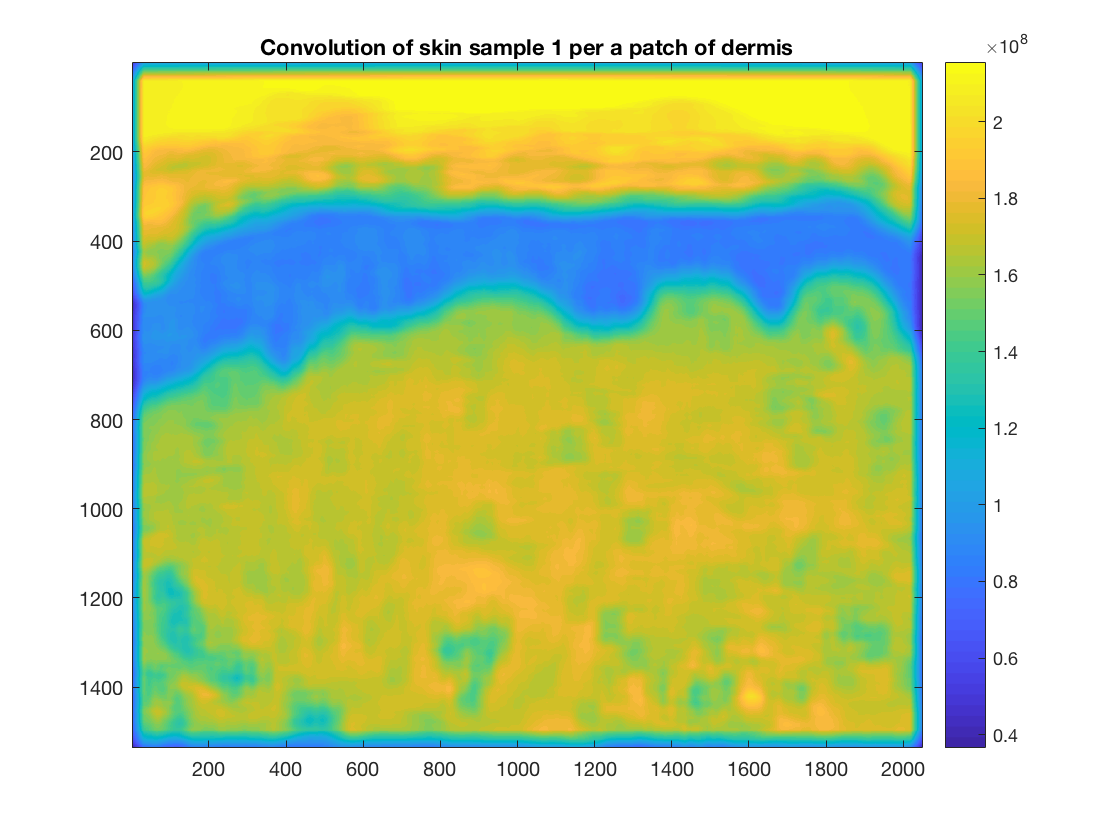

figure(5)
imagesc(feature_derme1);
title('Convolution of skin sample 1 per a patch of dermis'); colorbar;

Reconstruct the segmented image

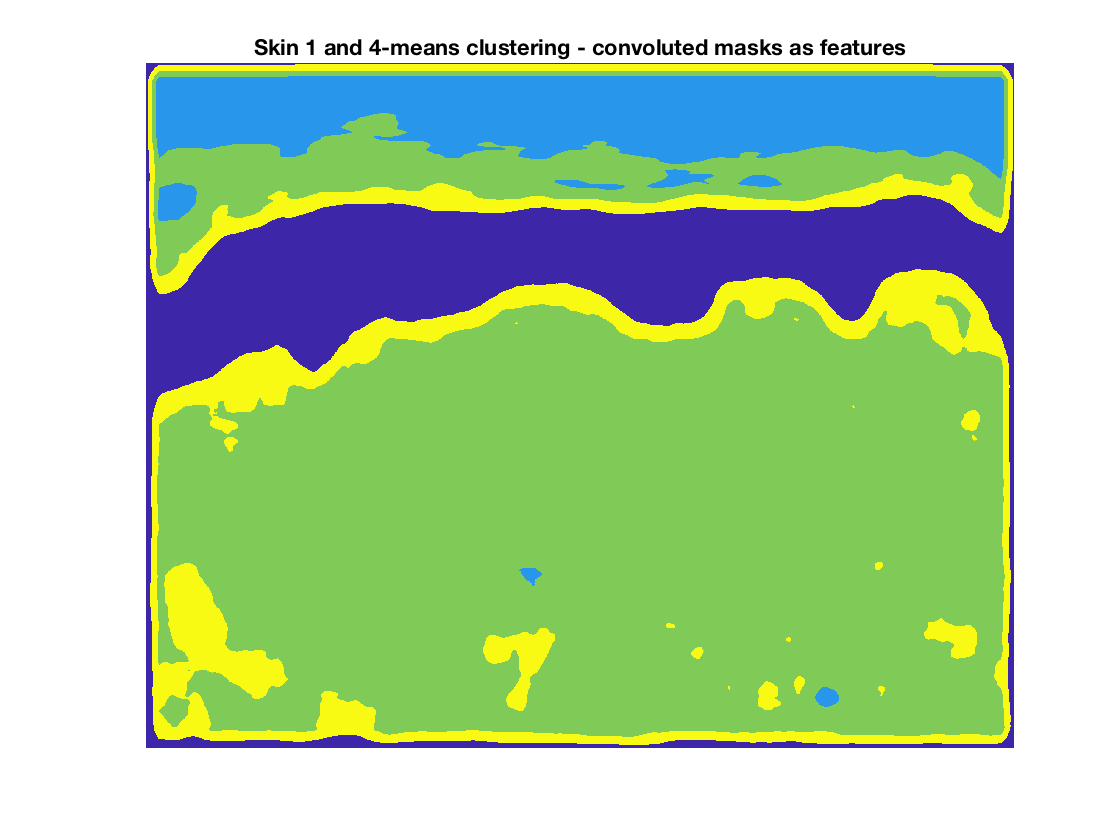

skin1F_reconstructed = reshape(idxSkinF1, m, n);

figure(6)
imagesc(skin1F_reconstructed);
title('Skin 1 and 4-means clustering - convoluted masks as features')
axis off;

*Observations:*

    The separation between dermis and epidermis using 4-means clustering is quite good except at the border between the zone which was expected.

We notice some edges effects because we force to identify 4 categories (dermis, epidermis, void and tumor) but in this example there is no tumor. Yet, we have to keep 4 classes if we want to build an automated tumor detector.

Thus, the problem is that we will identify some regions to be tumor while they are not (False positive). 

Yet, in the case where such algorithm may be used, this is not a problem since the doctor will notice that there is no tumor in this image.

## Skin sample 2

skin2G = double(rgb2gray(skin2));

kernel_derme2 = skin2G(560:610, 710:760);
kernel_epiderme2 = skin2G(86:104, 84:104);
kernel_tumeur2 = skin2G(130:140, 320:340);
feature_derme2 = imfilter(skin2G, kernel_derme2);
feature_epiderme2 = imfilter(skin2G, kernel_epiderme2);
feature_tumeur2 = imfilter(skin2G, kernel_tumeur2);

We also draw a feature map related to the dermis patch:

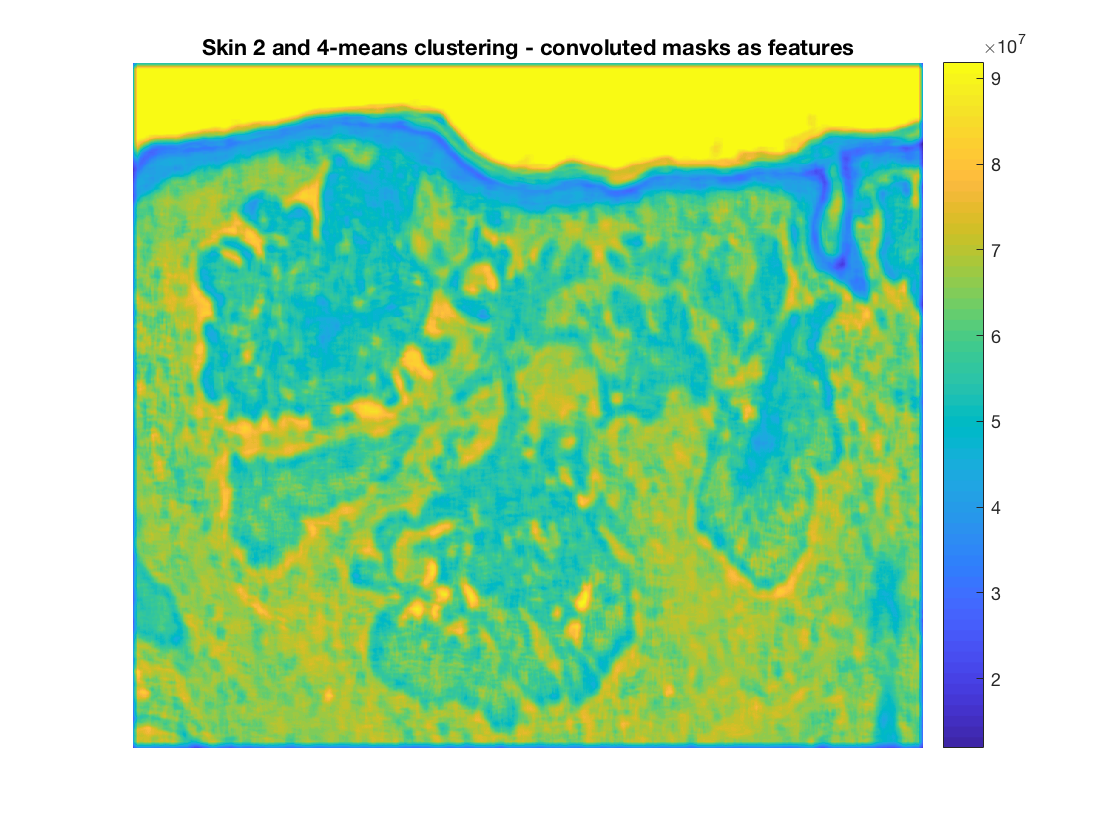

figure(7)
imagesc(feature_derme2);
title('Skin 2 and 4-means clustering - convoluted masks as features'); colorbar;
axis off;

*Observations:*

        The difference of intensity between the dermis and the tumor should enable a clear segmentation.

[m2, n2] = size(feature_derme2);
Xskin2 = [feature_derme2(:),...
          feature_tumeur2(:),...
          feature_epiderme2(:)];
idxSkinF2 = kmeans(Xskin2, 4);
skin2F_reconstructed = reshape(idxSkinF2, m2, n2);

We display the results of the 4-means clustering.

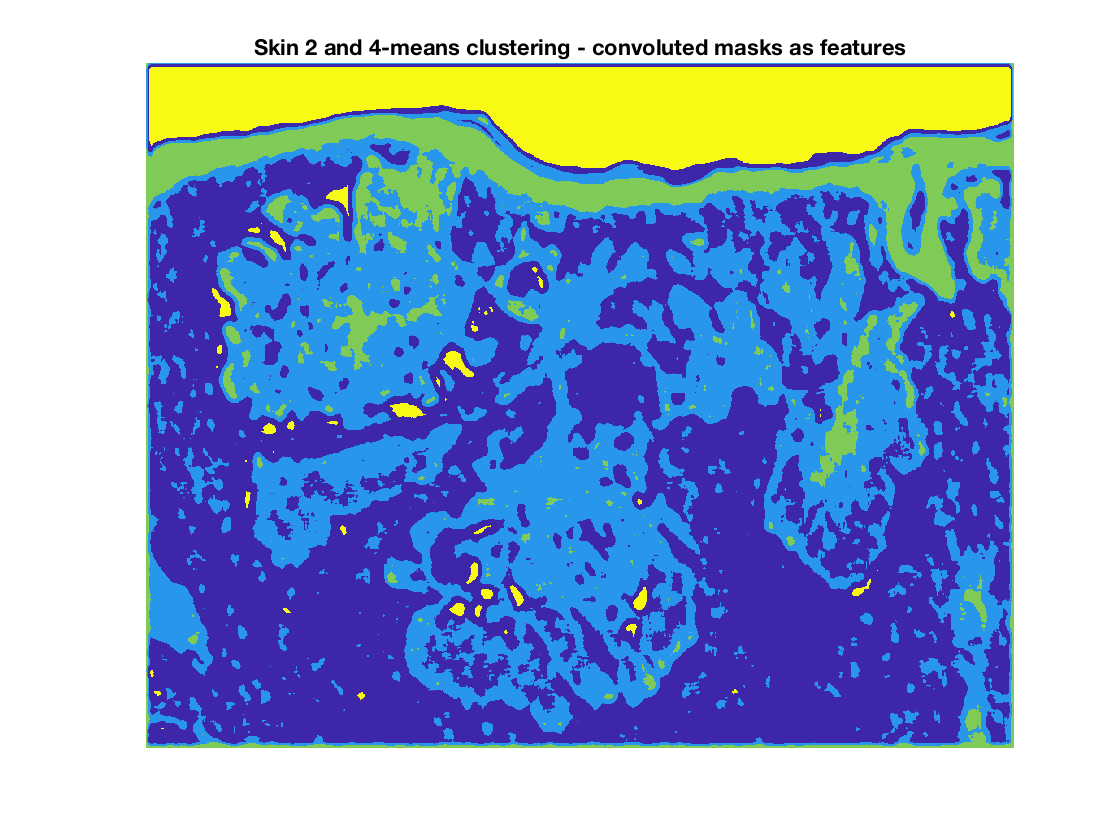

figure(8)
imagesc(skin2F_reconstructed);
title('Skin 2 and 4-means clustering - convoluted masks as features')
axis off;

*Observations:*

    We notice that the segmentation is not exact but it is much more accurate and useful compared to the 4-means using colors as features. 

The difference between dermis and tumor is quite hard to tell even for a human so it is no suprise that we have some patchwork of light and dark blue where we would have expected a strong separation.

In a nutshell, engineered features such as the convolution of the image with patch from the regions of interest had a positive impact on the results of the clustering.